# Curation of ecRhtoGEM

1.- Load ecRhtoGEM, in its batch format, in order to run simulations

load('models/ecRhtoGEM_batch.mat')
ecModel_batch

ecModel_batch = struct with fields:
                     id: 'ecRhtoGEM_batch_vv1.3.0'
            description: 'ecModel_batch of rhtoGEM'
             annotation: [1×1 struct]
                   rxns: {4838×1 cell}
                   mets: {2893×1 cell}
                      S: [2893×4838 double]
                     lb: [4838×1 double]
                     ub: [4838×1 double]
                    rev: [4838×1 double]
                      c: [4838×1 double]
                      b: [2893×1 double]
                  comps: {14×1 cell}
              compNames: {14×1 cell}
               rxnNames: {4838×1 cell}
                grRules: {4838×1 cell}
             rxnGeneMat: [4838×834 double]
             subSystems: {4838×1 cell}
                eccodes: {4838×1 cell}
             rxnMiriams: {4838×1 cell}
               rxnNotes: {4838×1 cell}
          rxnReferences: {4838×1 cell}
    rxnConfidenceScores: [4838×1 double]
                  genes: {834×1 cell}
         geneShortNames: {8

2.- Set glucose minimal media constraints for batch growth on simulations, run a FBA optimization and print the resulting exchange fluxes of the simulated phenotype

cd rhto_scripts
model = changeMedia_batch(ecModel_batch,'D-glucose exchange (reversible)');
cd ..
sol   = solveLP(model,1);
printFluxes(model,sol.x,true)

EXCHANGE FLUXES:
r_1634	(acetate exchange):	0.086167
r_1672	(carbon dioxide exchange):	0.18716
r_1832	(H+ exchange):	2.1438
r_2033	(pyruvate exchange):	2.0065
r_2100	(water exchange):	2.5436
r_2111	(growth):	0.027106
r_1654_REV	(ammonium exchange (reversible)):	0.11139
r_1714_REV	(D-glucose exchange (reversible)):	1.2497
r_1861_REV	(iron(2+) exchange (reversible)):	2.7106e-08
r_1992_REV	(oxygen exchange (reversible)):	1.1018
r_2005_REV	(phosphate exchange (reversible)):	0.0059457
r_2060_REV	(sulphate exchange (reversible)):	0.0023044
prot_pool_exchange	(prot_pool_exchange):	0.13344


3.- As the observed growth rate is around 9% of the expected value for batch growth on glucose (0.3 h-1, [Tiukova, et al. 2019](https://onlinelibrary.wiley.com/doi/full/10.1002/bit.27162)), one can conclude that the model is overconstrained. In order to figure out which are the enzymes with a major impact on this, GECKO returns a list of the top used enzymes in a model for a batch simulation (in terms of protein mass %). Display this list and analyse values:

topEnzymes =readtable('models/output_files/ecRhto-GEM_topUsedEnzymes.txt');
disp(topEnzymes)

    prots_Min_glucose    Usages_Min_glucose
    _________________    __________________

        'M7WT33'               0.98566     
        'M7WG08'              0.002371     
        'M7X6X3'              0.001272     
        'M7XKF0'              0.000945     
        'M7XBZ9'              0.000866     
        'M7WXM9'              0.000831     
        'M7X6S3'              0.000554     
        'M7WKX0'              0.000482     
        'M7WZC3'              0.000395     
        'M7WMT2'              0.000376     



4.- It can be seen that the enzyme M7WT33 accounts for 98.56% of the total protein mass available for metabolic enzymes, let's take a look to the reactions that this enzyme is connected to:

enzMet  = find(contains(model.metNames,'M7WT33'));
rxns    = find(model.S(enzMet,:));
constructEquations(model,rxns)

ans = 2×1 cell array
    {'pmet_r_0362[er] + 0.05176 prot_M7WT33[c] => dolichyl phosphate[er] + H+[er] + mannan[er]'}
    {'91.5306 prot_pool[c] => prot_M7WT33[c]'                                                  }


It turns out that M7WT33 is an isoenzyme, due to the presence of a constraint pseudometabolite (`pmet_r_0362`), let's all the reactions related to this pseudometabolite:

met  = find(contains(model.metNames,'pmet_r_0362'));
rxns    = find(model.S(met,:));
constructEquations(model,rxns)

ans = 4×1 cell array
    {'dolichyl D-mannosyl phosphate[er] => pmet_r_0362[er]'                                    }
    {'pmet_r_0362[er] + 0.05176 prot_M7XBY2[c] => dolichyl phosphate[er] + H+[er] + mannan[er]'}
    {'pmet_r_0362[er] + 0.05176 prot_M7WT33[c] => dolichyl phosphate[er] + H+[er] + mannan[er]'}
    {'pmet_r_0362[er] + 0.05176 prot_M7WZY6[c] => dolichyl phosphate[er] + H+[er] + mannan[er]'}


M7WT33 is an enzyme, out of three isoenzymes, that catalyses the following reaction

- `dolichyl D-mannosyl phosphate[er] => dolichyl phosphate[er] + H+[er] + mannan[er]`

Display its associated genes and E.C. number

disp(model.grRules(rxns(3)))

    'RHTO_02306'



disp(model.eccodes(rxns(3)))

    {''}



5.- There seems that the E.C. number information associated to this reaction or enzyme is not available in the model structure, therefore the encoding gene for `M7WT33` (`RHTO_02306`) needs to be queried in the [uniprot database](https://www.uniprot.org/).

It was found that the corresponding E.C. number is 2.4.1.109.

6.- More information about the limiting enzymes can be extracted from the list of flexibilized enzymes by the automated parameter calibration step in the GECKO toolbox. Display this list of enzymes, available in the directory of the ecModel output files:

flex_kcats = readtable('models/output_files/ecRhto-GEM_kcatModifications.txt')

flex_kcats = 8×10 table
    Unicode     enz_pos    rxn_pos               Organism                Modified    Parameter    oldValue    newValue     error     ControlCoeff
    ________    _______    _______    _______________________________    ________    _________    ________    ________    _______    ____________

    'M7WT33'     2440       3294      'saccharomyces cerevisiae'            1         'SA*Mw'     0.005367    0.005367    -95.818        10.844  
    'M7XI04'     2533       3398      'haloferax volcanii'                  1         'SA*Mw'     0.023001       18400    -95.651      0.039991  
    'M7WFB4'     2278       3055      'phaseolus vu

This list reveals that `M7WT33 `was also identified as the top limiting enzyme by the *kcat* flexibilization step, a further look into the table tells that GECKO was not able to find any alternative *kcat *for this enzyme. Moreover, a control coefficient $\left(\frac{\Delta v_{\mathrm{growth}} }{\Delta k_{\mathrm{cat}} }\right)$of 10.8443 was computed for this enzyme, which indicates that any unit increase in its associated *kcat *will induce a 10-fold increase in the maximum growth rate of the ecModel.

7.- As GECKO was not able to find any higher alternative parameter for this enzyme, a wild-card can be introduced in its E.C. number and then search for the  associated Kcat's for such class in the BRENDA data, also available in GECKO.

ECnumber   = '2.4.1.';
%open the full kcat database from GECKO
kcat_table = readtable('../../Databases/max_KCAT.txt');
%isolate those values reported for E.C.2.4.1.X
kcat_table = kcat_table(contains(kcat_table.Var1,ECnumber),:);
disp(['The Kcat data contains ' num2str(height(kcat_table)) ' entries for E.C.2.4.1.X enzymes'])

The Kcat data contains 611 entries for E.C.2.4.1.X enzymes


8.- As there are hundreds of parameters reported for this enzyme family, it is recommendable to search if any of them are reported for the modelled organism

rhto_kcats = kcat_table(contains(kcat_table.Var3,'toruloides') | contains(kcat_table.Var3,'gracilis'),:);
disp(['The Kcat data contains ' num2str(height(rhto_kcats)) ' entries for R. toruoloides or R. gracilis'])

The Kcat data contains 0 entries for R. toruoloides or R. gracilis


9.- As there are no parameters reported for the modelled organism then the distribution of kcat values for the E.C.2.4.1.X enzymes should be analysed:

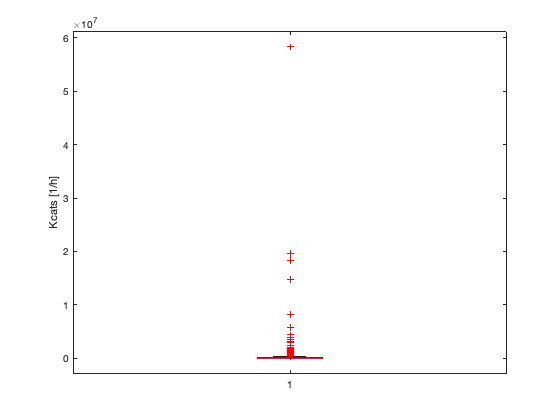

%convert kcats from 1/s to 1/h
kcats   = kcat_table.Var4*3600;
SDkcat  = std(kcats);
minkcat = min(kcats);
maxkcat = max(kcats);
medkcat = median(kcats);
avekcat = mean(kcats);
boxplot(kcats)
ylabel('Kcats [1/h]')

As the distribution spans multiple orders of magnitude, it is convenient to plot it in a log10 scale

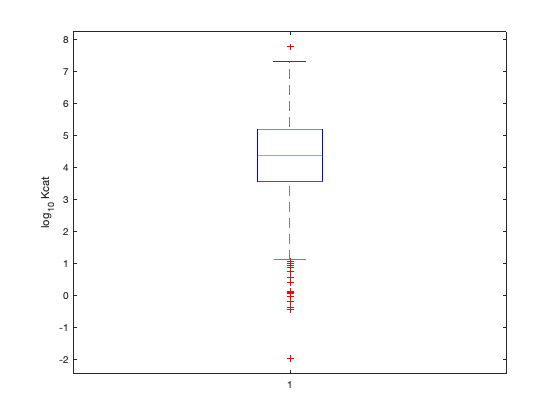

boxplot(log10(kcats))
ylabel('log_{10} Kcat')